    **MANUAL PCA METHOD USING EIGEN VECTORS** 

% Import data
data = rand(100, 2);

% Standardize the data
x_std = (data - mean(data, 1)) ./ std(data, 0, 1);

% Create a covariance matrix
c = cov(x_std)

c =     1.0000   -0.1776
   -0.1776    1.0000



% Eigenvalue and eigenvector decomposition
[evec, eval] = eig(c);

% Sort eigenvectors by eigenvalues in descending order
[~, order] = sort(diag(eval), 'descend');
evec = evec(:, order);

% Find the first principal component (PC)
pc = evec(:, 1);

% Project the data onto the first principal component (1D representation)
x_pca = x_std * pc;

% Reconstruct the 1D data back into 2D space (using the first principal component only)
y_1d = x_pca * pc'  % Projected back into 2D

y_1d =     1.0096   -1.0096
    0.0718   -0.0718
   -0.4054    0.4054
    0.5433   -0.5433
    0.6966   -0.6966
   -0.9568    0.9568
   -0.0670    0.0670
   -0.2903    0.2903
    0.3403   -0.3403
    0.2510   -0.2510


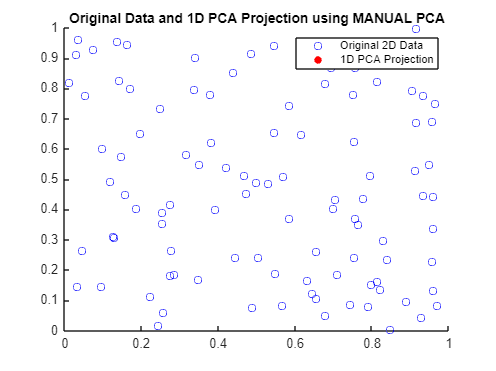


% Plotting the original 2D data and the 1D reduced data
figure;
scatter(data(:, 1), data(:, 2), 'b'); % Original data in blue
hold on;
scatter(y_1d(:, 1), y_1d(:, 2), 'r', 'filled'); % 1D reduced data in red
title('Original Data and 1D PCA Projection using MANUAL PCA');
legend('Original 2D Data', '1D PCA Projection');
xlim([0,1])
ylim([0,1])
hold off;

**USING MATLAB's PCA FUNCTION**

% Apply PCA using MATLAB's built-in function
[coeff, score, ~,~,explained,mu] = pca(x_std);

% The principal component is the first column of 'coeff'
pc1 = coeff(:, 1);

% Project the data onto the first principal component (1D representation)
x_pca1 = score(:, 1) ; % This is the 1D reduced data

% Reconstruct the 1D data back into 2D space (using the first principal component only)
y__1d = x_pca * pc'  % Projected back into 2D

y__1d =     1.0096   -1.0096
    0.0718   -0.0718
   -0.4054    0.4054
    0.5433   -0.5433
    0.6966   -0.6966
   -0.9568    0.9568
   -0.0670    0.0670
   -0.2903    0.2903
    0.3403   -0.3403
    0.2510   -0.2510


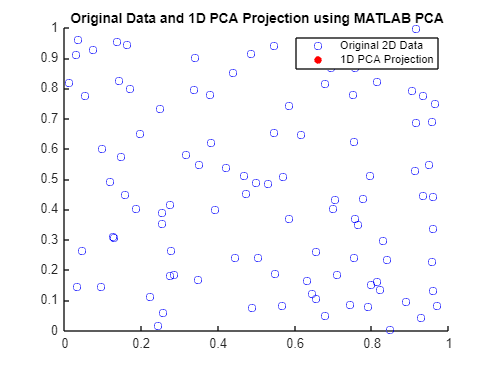


% Plotting the original 2D data and the 1D reduced data
figure;
scatter(data(:, 1), data(:, 2), 'b'); % Original data in blue
hold on;
scatter(y__1d(:, 1), y__1d(:, 2), 'r', 'filled'); % 1D reduced data in red
title('Original Data and 1D PCA Projection using MATLAB PCA');
legend('Original 2D Data', '1D PCA Projection');
xlim([0,1])
ylim([0,1])
hold off;


% Display variance explained by each principal component
disp('Variance explained by each component:');

Variance explained by each component:


disp(explained);

   58.8787
   41.1213

